# **DCBT 2022: fMRI Project**

**Alpha-Gamma Group**

Sept 2022


% data input (from mini NYC-Q mind wandering test)
% 10 subjects

s1 = [90	0	100	100	80	100	100	95	0	100	90	30];
s2 = [85	35	85	5	100	100	25	30	55	85	100	75];
s3 = [80	30	50	70	40	100	15	60	100	0	65	90];
s4 = [60	35	75	25	45	35	20	50	80	40	80	40];
s5 = [70	30	75	60	40	70	25	25	50	25	65	35];
s6 = [35	35	40	45	40	35	45	35	40	40	70	10];
s7 = [85	10	60	75	20	65	5	30	95	15	65	35];
s8 = [55	45	35	45	15	55	0	40	95	55	65	65];
s9 = [75	5	65	60	70	80	40	75	65	0	70	20];
s10 = [55	60	20	60	40	65	65	30	90	55	20	15];

% acummulate input into one matrix
S = [s1
    s2
    s3
    s4
    s5
    s6
    s7
    s8
    s9
    s10];

% normalize the matrix
S = S/100;

% initiate an empty matrix for the results
m = zeros([10,10])

m =      0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


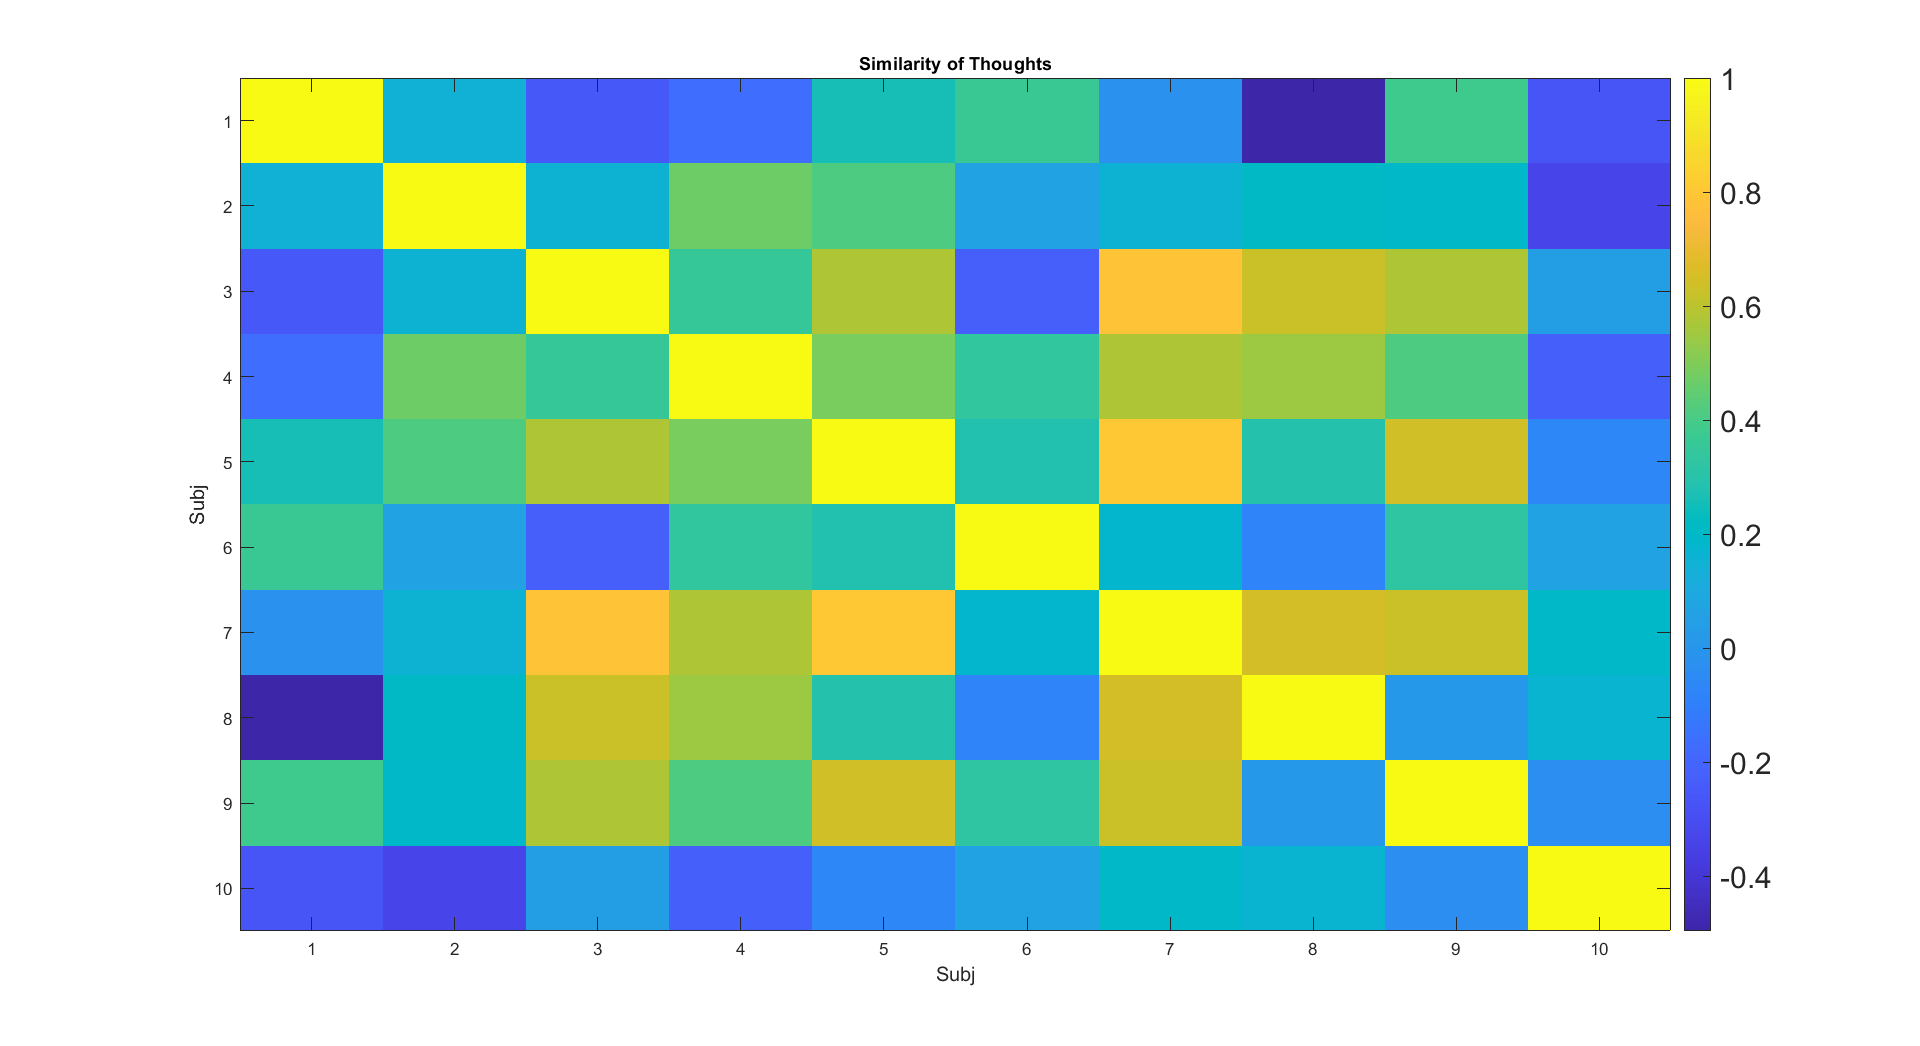


% alternative 1: computing distances

% for i=1:10
%     for j=1:10
%         s_i = S(i,:);
%         s_j = S(j,:);
%         m(i , j) = pdist([s_i; s_j]);
%     end
% end

% m = m/max(m,[],'all')

% alternative 2: compute Spearman correlation
m = corrcoef(S');

fig = figure(2);
imagesc(m);
colorbar('FontSize', 18);
xlabel('Subj', 'FontSize',12)
ylabel('Subj', 'FontSize',12)

fig.Visible='on';
t = title('Similarity of Thoughts');